# Plot Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

dates = readmatrix("./data/electricityData.xlsx", Sheet="dates", OutputType="datetime");
sectors = readmatrix("./data/electricityData.xlsx", Sheet="sectors", OutputType="string");
usage = readmatrix("./data/electricityData.xlsx", Sheet="usage");
whos

  Name              Size            Bytes  Class       Attributes

  data              9x3              1633  table                 
  dates           315x1              2520  datetime              
  gdpMedCorr        2x2                32  double                
  sectors           1x4               360  string                
  usage           315x4             10080  double                
  usagecorr         4x4               128  double                



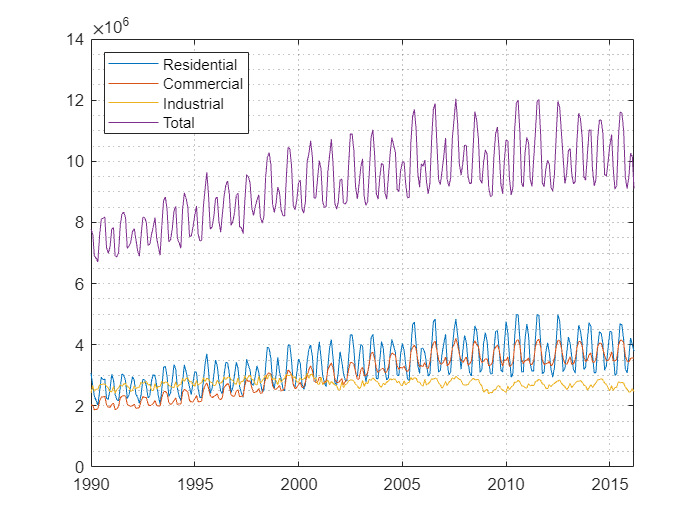

plot(dates, usage)
grid minor
legend(sectors, "Location", "northwest")

## Task 1

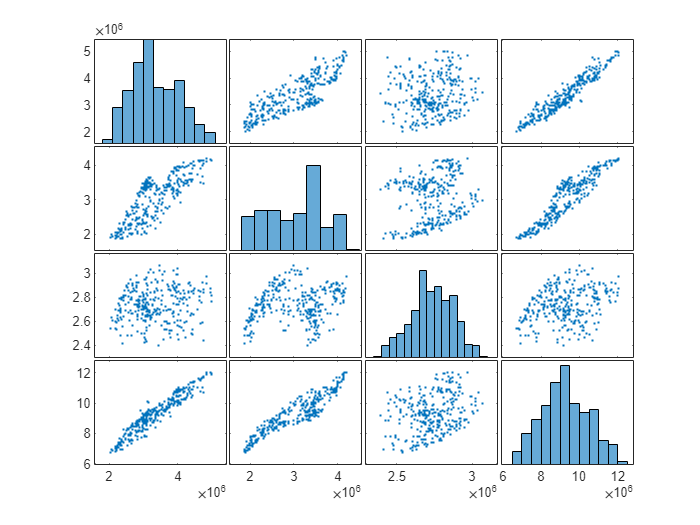

plotmatrix(usage)
grid minor

## Task 2

You can see in the scatter plots that some columns appear more correlated than others. You can pass a matrix to the `corrcoef` function to quantify these correlations.

usagecorr = corrcoef(usage)

usagecorr =     1.0000    0.8243    0.1300    0.9519
    0.8243    1.0000    0.1591    0.9268
    0.1300    0.1591    1.0000    0.2938
    0.9519    0.9268    0.2938    1.0000
